### **Group: Aleix Granero, Michal Szabó**

**10.11.2021**

close all; clc; clear

# Practice 5. Morphological operators.

## Exercise 1

I = imread('text.tif');

#### ** 1. Binarization of the input image**

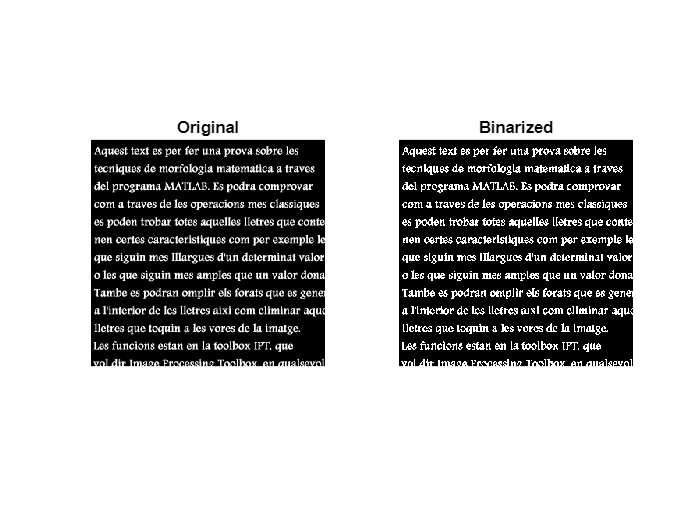

f = imbinarize(I,"global");
figure
subplot(1,2,1), imshow(I), title('Original')
subplot(1,2,2), imshow(f), title('Binarized')

#### **Comparing the results of the following functions on a binarized sample image (f)**

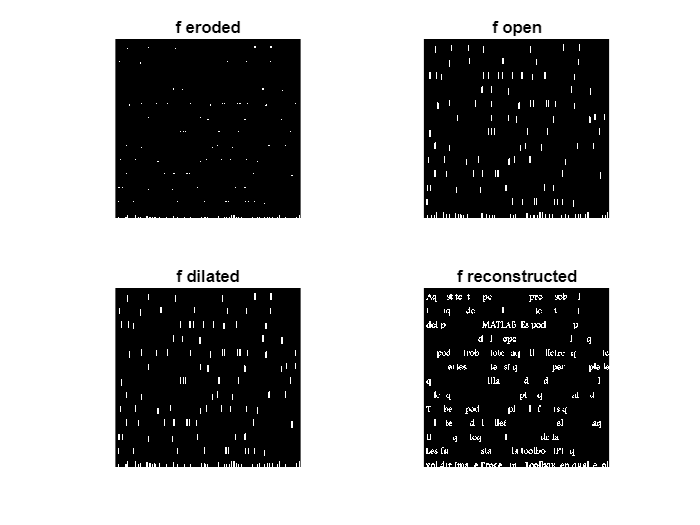

fe = imerode(f, ones(10,1));
fo = imopen(f, ones(10,1));
fd = imdilate(fe, ones(10,1));
fobr = imreconstruct(fe,f);

figure
subplot(2,2,1), imshow(fe), title('f eroded')
subplot(2,2,2), imshow(fo), title('f open')
subplot(2,2,3), imshow(fd), title('f dilated')
subplot(2,2,4), imshow(fobr), title('f reconstructed')

#### a) Only characters that match with the white pixels of the pattern

- **Mask 1**

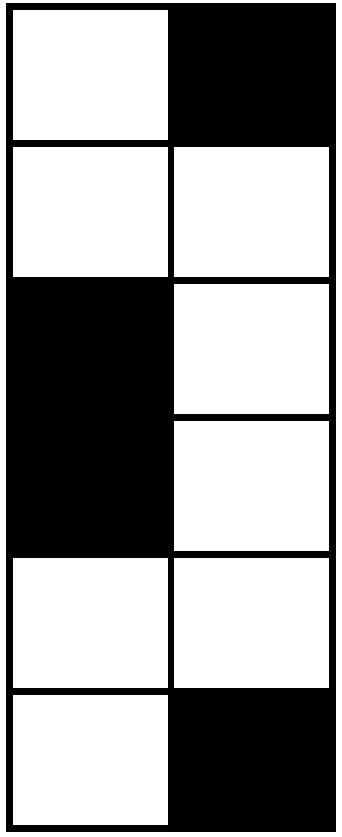

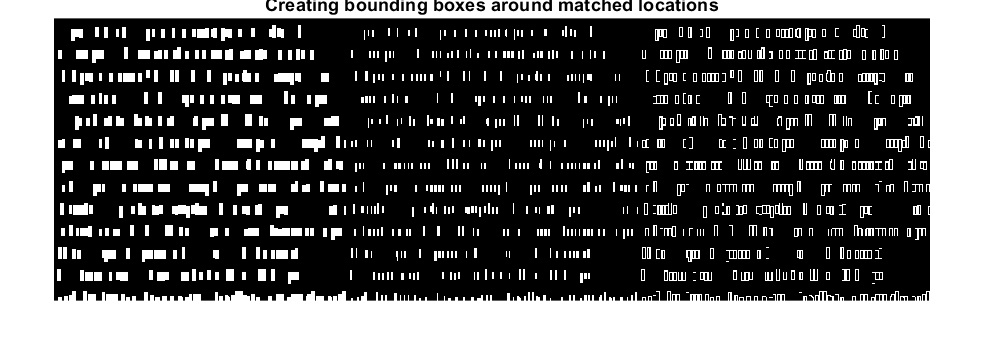


mask_W1 = [1 0;1 1;0 1;0 1;1 1;1 0];
match_W1 = imerode(f,mask_W1);

% Mask for highlighting the results
f_mask = ones(8,4);     % Around the located area
f_mask_e = ones(6,2);   % minus the inside

% Highlighting locations
match_W_res = imdilate(match_W1,f_mask);
match_W_res_e = imdilate(match_W1,f_mask_e);
match = match_W_res-match_W_res_e;
figure
montage({match_W_res,match_W_res_e,match},'Size',[1 3])
title('Creating bounding boxes around matched locations')

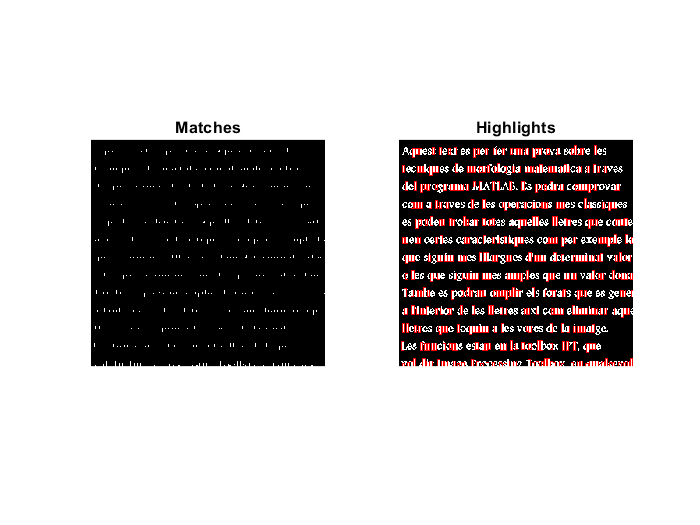

% Representing the solution in color
result_a = cat(3,f+match,f-match,f-match);
figure
subplot(1,2,1), imshow(match_W1), title('Matches')
subplot(1,2,2), imshow(result_a), title('Highlights')

- **Mask 2**

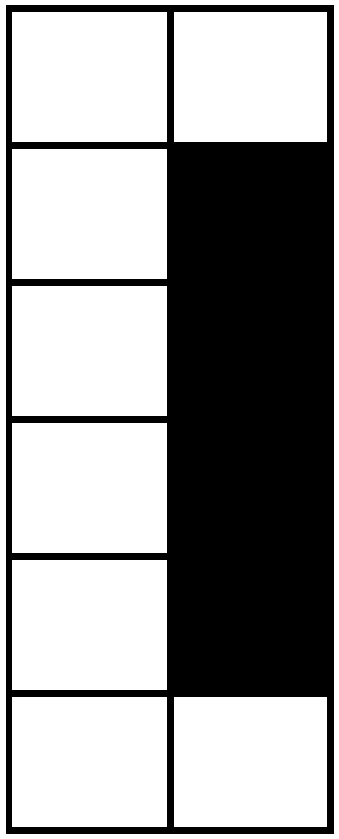

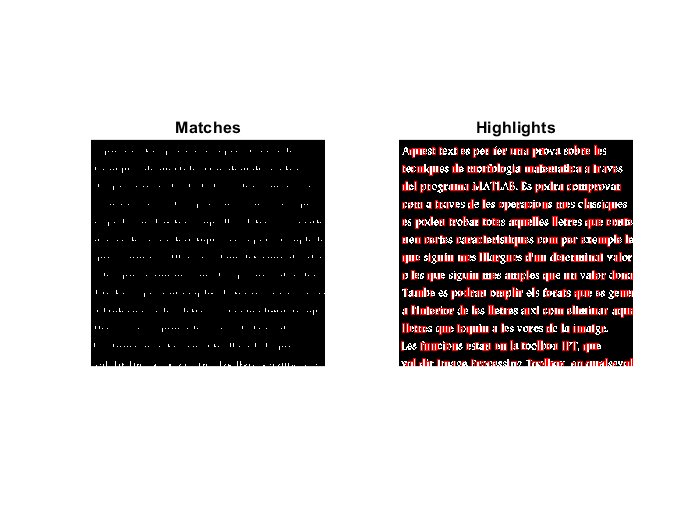

mask_W2 = [1 1;1 0;1 0;1 0;1 0;1 1];
match_W2 = imerode(f,mask_W2);

% Highlighting locations
match_W_res = imfill(imdilate(match_W2,f_mask),'holes');
match_W_res_e = imdilate(match_W2,f_mask_e);
match = match_W_res-match_W_res_e;
result_a = cat(3,f+match,f-match,f-match);

figure
subplot(1,2,1), imshow(match_W2), title('Matches')
subplot(1,2,2), imshow(result_a), title('Highlights')

#### b) Characters that match with the White AND the Black pixels of the pattern

- **Mask 1**

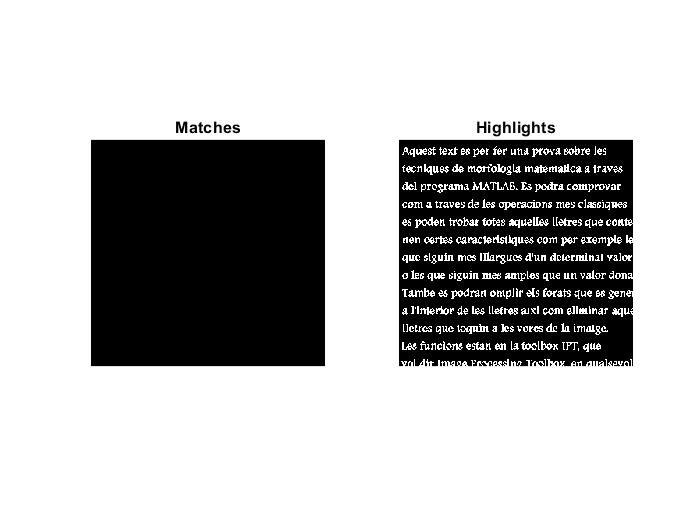

% Mask 1 for detecting black pixels
mask_B1 = ~mask_W1;

% Detection of black pixels
match_B1 = imerode(~f,mask_B1)-(~f);
match_B1(match_B1==-1) = 0; % Changing -1 to zero created when substracting ~f

% Finding intersection of white AND black mask
match_WB1 = and(match_W1,match_B1);

% Highlighting locations
match_WB_res = imfill(imdilate(match_WB1,f_mask),'holes');
match_WB_res_e = imdilate(match_WB1,f_mask_e);
match = match_WB_res-match_WB_res_e;
result_b = cat(3,f+match,f-match,f-match);
figure
subplot(1,2,1), imshow(match_B1), title('Matches')
subplot(1,2,2), imshow(result_b), title('Highlights')

- **Mask 2**

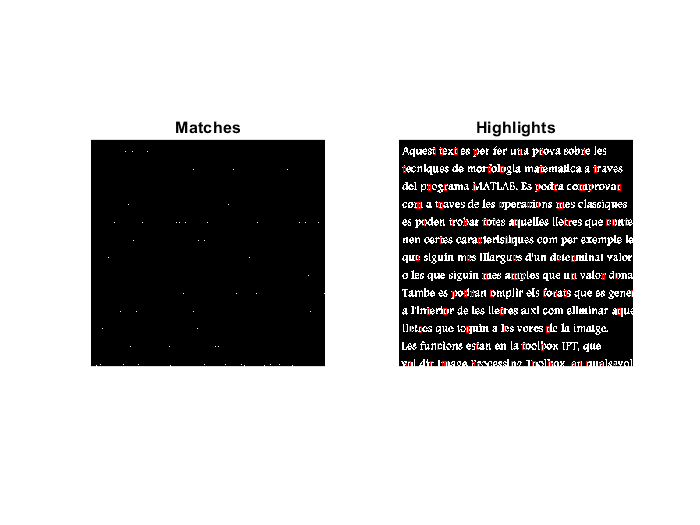

% match_WB2 = bwhitmiss(f,mask_W1,~mask_W1);
% match_WB_res = imfill(imdilate(match_WB2,f_mask),'holes');
% % figure, imshow(match_WB_res)
% match_WB_res_e = imdilate(match_WB2,f_mask_e);
% match = match_WB_res-match_WB_res_e;
% result_b = cat(3,f+match,f-match,f-match);
% figure
% subplot(1,2,1), imshow(match_WB2), title('Erosion')
% subplot(1,2,2), imshow(result_b), title('Higlights')
% Mask 2 for detecting black pixels

mask_B2 = ~mask_W2;

% Detection of black pixels
match_B2 = imerode(~f,mask_B2)-(~f);
match_B2(match_B2==-1) = 0; % Changing -1 to zero created when substracting ~f

% Finding intersection of white AND black mask
match_WB2 = and(match_W2,match_B2);

% Highlighting locations
match_WB_res = imfill(imdilate(match_WB2,f_mask),'holes');
match_WB_res_e = imdilate(match_WB2,f_mask_e);
match = match_WB_res-match_WB_res_e;
result_b = cat(3,f+match,f-match,f-match);
figure
subplot(1,2,1), imshow(match_WB2), title('Matches')
subplot(1,2,2), imshow(result_b), title('Highlights')

#### 3. Find those characters that match with white AND black pixels of the next patterns, but taking into account don’t care pixels X (marked in gray with a X).

- **Mask 1**

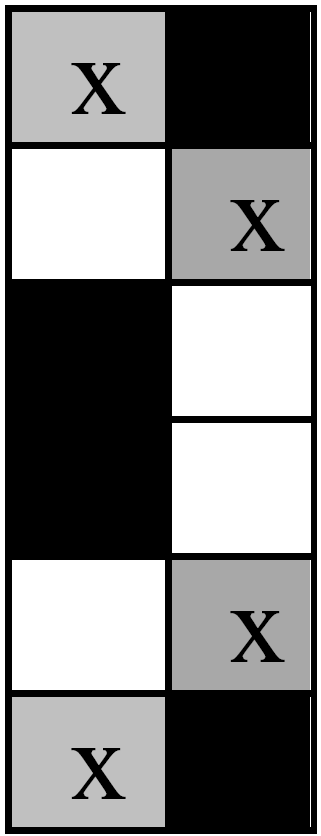

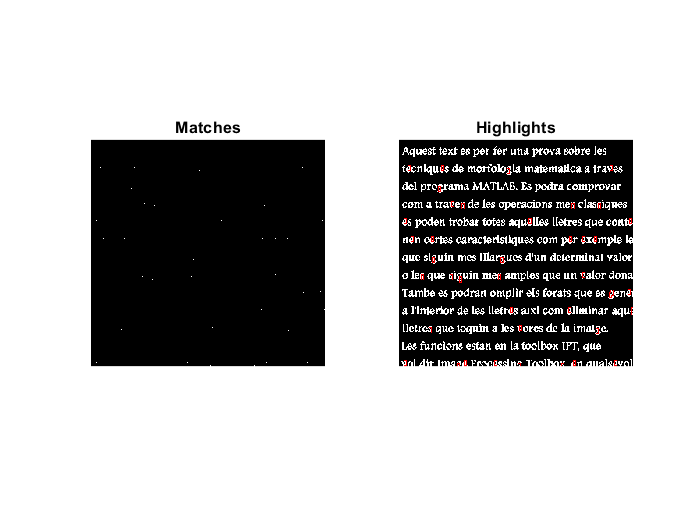

% Masks
mask_Wx1 = [0 0;1 0;0 1;0 1;1 0;0 0];
mask_Bx1 = [0 1;0 0;1 0;1 0;0 0;0 1];

% White
match_Wx1 = imerode(f,mask_Wx1);

% Black
match_Bx1 = imerode(~f,mask_Bx1)-(~imdilate(f,strel('disk',1,0)));
match_Bx1(match_Bx1==-1) = 0;

% Logical AND of both
match_WBx1 = and(match_Wx1,match_Bx1);

% Dysplaying results
match_WBx_res = imfill(imdilate(match_WBx1,f_mask),'holes');
match_WBx_res_e = imdilate(match_WBx1,f_mask_e);
match_x = match_WBx_res-match_WBx_res_e;
result_x = cat(3,f+match_x,f-match_x,f-match_x);
figure
subplot(1,2,1), imshow(match_WBx1), title('Matches')
subplot(1,2,2), imshow(result_x), title('Highlights')

- **Mask 2**

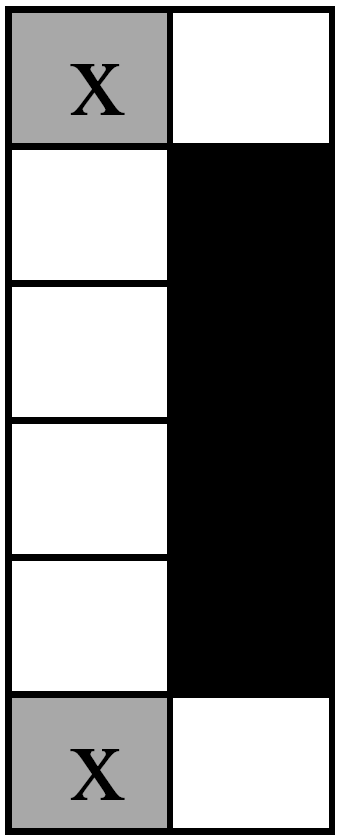

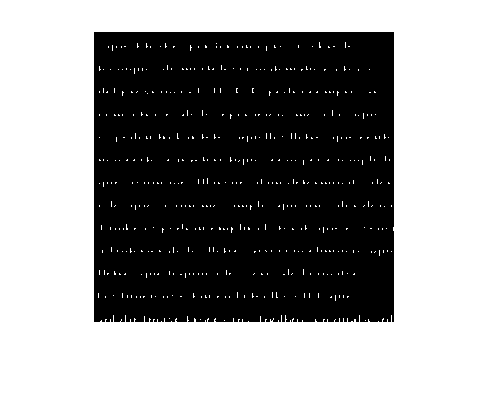

% Masks
mask_Wx2 = [0 1;1 0;1 0;1 0;1 0;0 1];
mask_Bx2 = [0 0;0 1;0 1;0 1;0 1;0 0];

% White
match_Wx2 = imerode(f,mask_Wx2);
figure, imshow(match_Wx2)

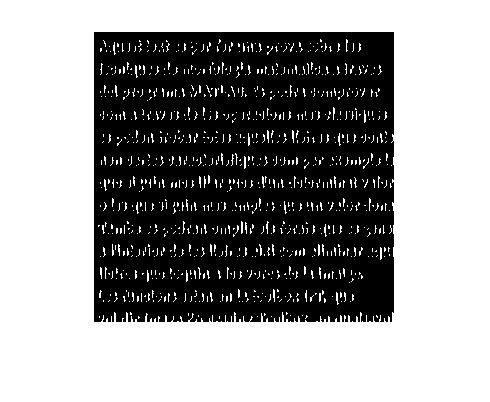


% Black
match_Bx2 = imerode(~f,mask_Bx2);%-(~f);
% figure
% montage({match_Bx2,~f},'Size',[1 2]) 
match_Bx2 = imerode(~f,mask_Bx2)-(~imdilate(f,strel('disk',1,0)));
match_Bx2(match_Bx2==-1) = 0;
figure, imshow(match_Bx2)

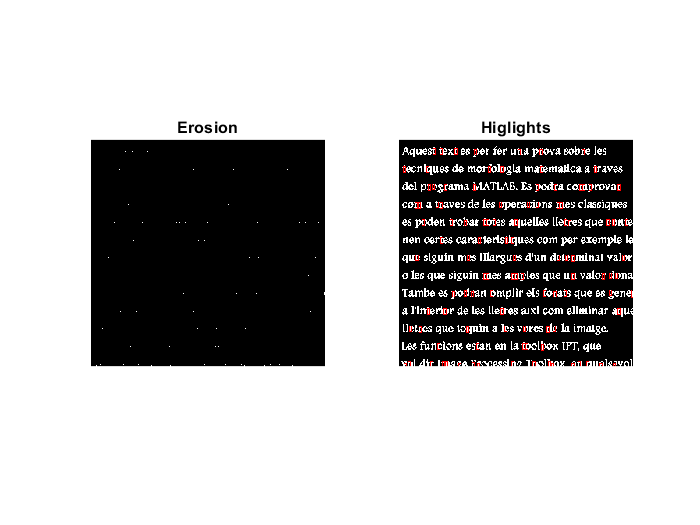


% Logical AND of both
match_WBx2 = and(match_Wx2,match_Bx2);

% Dysplaying results
match_WBx_res = imfill(imdilate(match_WBx2,f_mask),'holes');
match_WBx_res_e = imdilate(match_WBx2,f_mask_e);
match_x = match_WBx_res-match_WBx_res_e;
result_x = cat(3,f+match_x,f-match_x,f-match_x);
figure
subplot(1,2,1), imshow(match_WBx2), title('Erosion')
subplot(1,2,2), imshow(result_x), title('Higlights')

% Comparison
% match_WB2 = bwhitmiss(f,mask_Wx2,mask_Bx2);
% match_WB_res = imfill(imdilate(match_WB2,f_mask),'holes');
% % figure, imshow(match_WB_res)
% match_WB_res_e = imdilate(match_WB2,f_mask_e);
% match = match_WB_res-match_WB_res_e;
% result_b = cat(3,f+match,f-match,f-match);
% figure
% subplot(1,2,1), imshow(match_WB2), title('Matches')
% subplot(1,2,2), imshow(result_b), title('Highlights')

## Exercise 2

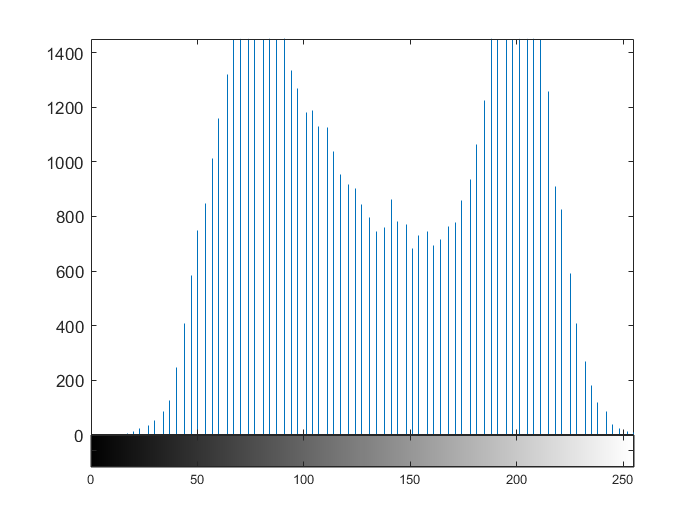

I = imread('bloodcells.tif');
figure, imhist(I)

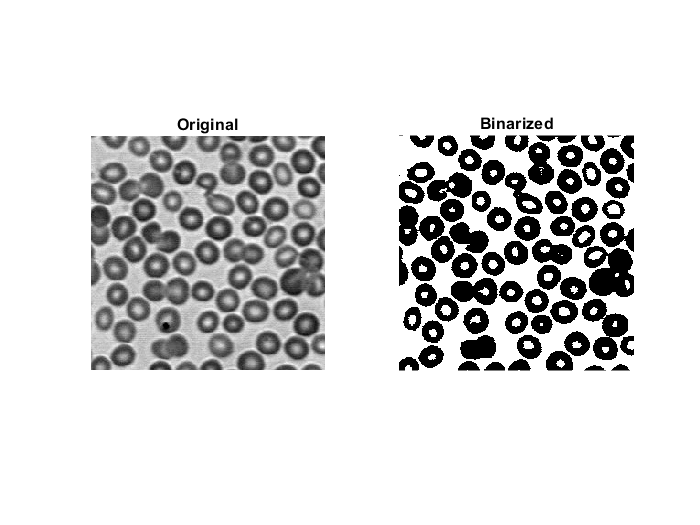

bin_I = imbinarize(I,0.55);
% bin_I = imbinarize(I,0.35);
% bin_I = imclose(~bin_I,strel('disk',3,0));

figure
subplot(1,2,1), imshow(I), title('Original')
subplot(1,2,2), imshow(bin_I), title('Binarized')

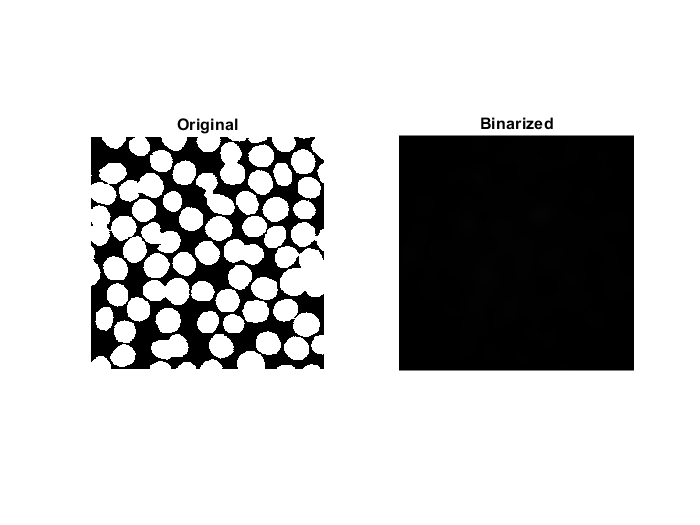

bin_I(1,:) = 0;
bin_I(size(bin_I,1),:) = 0;
bin_I(:,size(bin_I,2)) = 0;

I1 = imfill(~bin_I,'holes');
figure
subplot(1,2,1), imshow(I1), title('Original')
subplot(1,2,2), imshow(frst2d(I1, 80, 2, 0.1, 'bright')), title('Binarized')

** 1. Counting the number of cells in the image.**

I2 = imopen(I1,strel('disk',1,0));

blobMeasurements = regionprops(I2,'Perimeter','Area','Centroid','BoundingBox')

blobMeasurements = 71×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    Perimeter


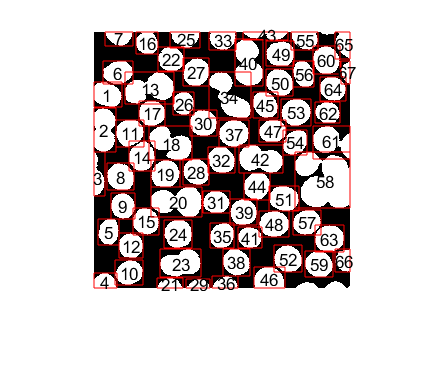

% Variables
P_all = [];     % Perimeter
A_all = [];     % Area
C_all = [];     % Centroid 
BB_all = [];    % Bounding Box

for i = 1:length(blobMeasurements)
    P_all(i) = blobMeasurements(i).Perimeter;
    A_all(i) = blobMeasurements(i).Area;
    C_all = [C_all;blobMeasurements(i).Centroid];
    BB_all = [BB_all;blobMeasurements(i).BoundingBox];
end

%% In case we find an object that is not a usual size this code will handle the problem
% Interval for only areas of the cells
n = (A_all>100).*(A_all<2500);

% Bottle Areas
A = (A_all.*n)';
A(A==0) = [];

% Bottle Perimeters
P = (P_all.*n)';
P(P==0) = [];

% Bottle Centroids
C = C_all.*n';
C(C==0) = [];
C = reshape(C,[length(C)/2 2]);

% Bottle Bounding Boxes
BB = BB_all.*n';
BB(BB==0) = [];
BB = reshape(BB,[length(BB)/4 4]);

% Displaying results
figure, imshow(I2), hold on,
for i = 1:size(BB,1)
    rectangle('Position',BB(i,:),'EdgeColor','r'),
    text(C(i,1),C(i,2),num2str(i),'HorizontalAlignment','center')
end
hold off

**2. Finding the center of the mass of each cell**

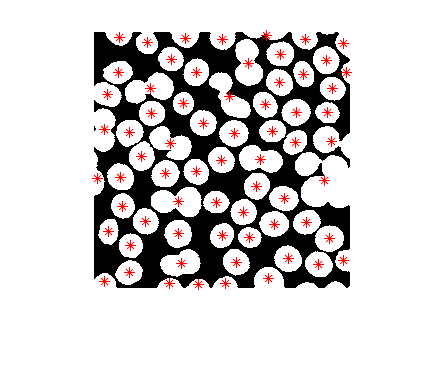

figure, imshow(I2), hold on,
plot(C(:,1),C(:,2),'r*')
hold off

**3. Finding rectangularity coefficient R of each cell**

for i = 1:length(A)
    R(i) = A(i)/(BB(i,3)*BB(i,4));
end
Rectangularity = R

Rectangularity =     0.7700    0.8140    0.5537    0.7971    0.7399    0.7594    0.7117    0.7791    0.7516    0.7229    0.7540    0.7833    0.6422    0.7410    0.7607    0.8140    0.8046    0.6033    0.7637    0.7170    0.7115    0.7772    0.7021    0.7742    0.7271    0.7909    0.7596    0.7648    0.7083    0.7849    0.7660    0.7792    0.7963    0.4798    0.7800    0.7147    0.7556    0.7476    0.7650    0.7401    0.7560    0.7208    0.6694    0.7835    0.7600    0.8218    0.8013    0.7641    0.7786    0.7641


**4. Finding the circularity coefficient C for each cell**

for i = 1:length(A)
    Cir(i) = P(i)^2/A(i);
end
Circularity = Cir

Circularity =    12.7632   16.6353   33.5635   13.7264   12.5650   12.4950   15.8151   12.3422   11.7366   11.9818   11.9970   12.1758   19.3577   12.1861   12.4649   12.8420   11.6836   19.8222   12.2806   18.3940   17.4895   12.5752   14.5826   12.0145   15.5687   11.5050   12.1639   11.9095   17.8668   11.9923   12.1545   12.0236   14.8874   23.5326   11.7224   16.6369   12.2395   12.5801   11.9371   17.3511   11.8978   15.4261   39.0222   11.8679   11.9646   13.9900   11.8702   12.0757   12.3997   12.1668
